s=30

s = 30

a=5

a = 5

test1 = rand(1,s)

test1 =     0.8147    0.9058    0.1270    0.9134    0.6324    0.0975    0.2785    0.5469    0.9575    0.9649    0.1576    0.9706    0.9572    0.4854    0.8003    0.1419    0.4218    0.9157    0.7922    0.9595    0.6557    0.0357    0.8491    0.9340    0.6787    0.7577    0.7431    0.3922    0.6555    0.1712


test2 = rand(1,s)

test2 =     0.7060    0.0318    0.2769    0.0462    0.0971    0.8235    0.6948    0.3171    0.9502    0.0344    0.4387    0.3816    0.7655    0.7952    0.1869    0.4898    0.4456    0.6463    0.7094    0.7547    0.2760    0.6797    0.6551    0.1626    0.1190    0.4984    0.9597    0.3404    0.5853    0.2238


testc = 1:s

testc =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


testn = rand(1,s);
testn = testn<0.5;
testn = testn*2-1

testn =     -1     1    -1    -1    -1    -1    -1     1     1     1    -1     1    -1     1    -1     1     1     1    -1     1     1    -1    -1    -1    -1     1    -1    -1     1    -1


test = zeros(s, 2);
test(:,1) = (testc+testn.*test1/10)';
test(1,1) = 1;
test(:,2) = (a*test2)'

test =     1.0000    3.5302
    2.0906    0.1592
    2.9873    1.3846
    3.9087    0.2309
    4.9368    0.4857
    5.9902    4.1173
    6.9722    3.4741
    8.0547    1.5855
    9.0958    4.7511
   10.0965    0.1722


test_rs = resample(test(:,2),test(:,1),1)

test_rs =     3.5302
    0.4392
    1.3687
    0.2535
    0.7036
    4.1109
    3.4256
    1.6809
    4.4600
    0.6137


test_rsp1 = resample(test(1:s/2,2),test(1:s/2,1),1)

test_rsp1 =     3.5302
    0.4392
    1.3687
    0.2535
    0.7036
    4.1109
    3.4256
    1.6809
    4.4600
    0.6137


if size(test_rsp1,1)<s/2
    test_rsp2 = [test(s/2-1:end,1),test(s/2-1:end,2)];
    test_rsp2(1,:) = [testc(s/2-1), test_rsp1(end)];
else
    test_rsp2 = [test(s/2:end,1),test(s/2:end,2)];
    test_rsp2(1,:) = [testc(s/2), test_rsp1(end)];
end

test_rsp2

test_rsp2 =    14.0000    3.9697
   14.9200    0.9344
   16.0142    2.4488
   17.0422    2.2279
   18.0916    3.2316
   18.9208    3.5468
   20.0959    3.7734
   21.0656    1.3801
   21.9964    3.3985
   22.9151    3.2755


test_rsp2 = resample(test_rsp2(:,2),test_rsp2(:,1),1)

test_rsp2 =     3.9697
    1.0451
    2.4292
    2.2370
    3.1440
    3.5621
    3.7549
    1.5420
    3.3980
    3.0646



test_rspC = cat(1, test_rsp1(1:end),test_rsp2(2:end))

test_rspC =     3.5302
    0.4392
    1.3687
    0.2535
    0.7036
    4.1109
    3.4256
    1.6809
    4.4600
    0.6137


if size(test_rspC,1)<s
    test_rspC(s,:) = test(end,2);
end
size(test_rs)

ans =     29     1


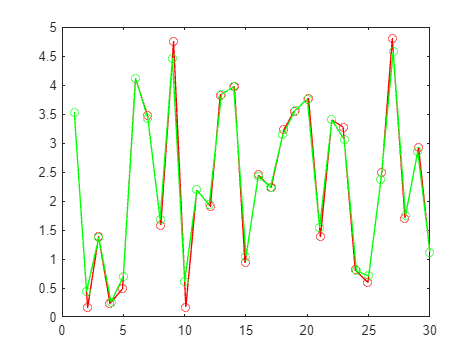

if size(test_rs,1)<s
    test_rs(s,:) = test(end,2);
end
figure
plot(test(:,1),test(:,2),'r-o',testc, test_rs, 'b-o', testc, test_rspC, 'g-o')

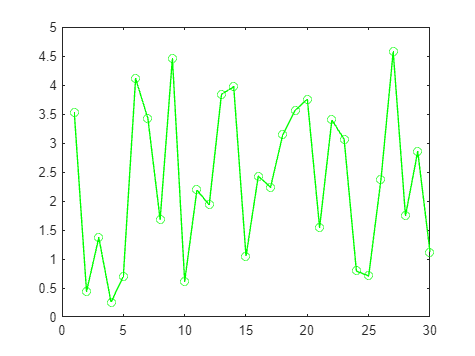

plot(testc, test_rs, 'b-o', testc, test_rspC, 'g-o')

sum((test_rspC~=test_rs))

ans = 0

siz = 10;
tpoints = rand(1,2)

tpoints =     0.0759    0.0540


%tpoints = (tpoints-min(tpoints))/(max(tpoints-min(tpoints)))
tpoints = round(tpoints*(siz-2))

tpoints =      1     0


tpoints = tpoints+1

tpoints =      2     1


amountmat = zeros(1,siz);
amountmat(tpoints) = 1

amountmat =      1     1     0     0     0     0     0     0     0     0


listS = 100;
rand

ans = 0.5308

numbs = tpoints'+rand(1,listS/2)

numbs =     2.7792    2.9340    2.1299    2.5688    2.4694    2.0119    2.3371    2.1622    2.7943    2.3112    2.5285    2.1656    2.6020    2.2630    2.6541    2.6892    2.7482    2.4505    2.0838    2.2290    2.9133    2.1524    2.8258    2.5383    2.9961    2.0782    2.4427    2.1067    2.9619    2.0046    2.7749    2.8173    2.8687    2.0844    2.3998    2.2599    2.8001    2.4314    2.9106    2.1818    2.2638    2.1455    2.1361    2.8693    2.5797    2.5499    2.1450    2.8530    2.6221    2.3510
    1.7792    1.9340    1.1299    1.5688    1.4694    1.0119    1.3371    1.1622    1.7943    1.3112    1.5285    1.1656    1.6020    1.2630    1.6541    1.6892    1.7482    1.4505    1.0838    1.2290    1.9133    1.1524    1.8258    1.5383    1.9961    1.0782    1.4427    1.1067    1.9619    1.0046    1.7749    1.8173    1.8687    1.0844    1.3998    1.2599    1.8001    1.4314    1.9106    1.1818    1.2638    1.1455    1.1361    1.8693    1.5797    1.5499    1.1450    1.8530    1.6221 

numbs = reshape(numbs, 1,listS)

numbs =     2.7792    1.7792    2.9340    1.9340    2.1299    1.1299    2.5688    1.5688    2.4694    1.4694    2.0119    1.0119    2.3371    1.3371    2.1622    1.1622    2.7943    1.7943    2.3112    1.3112    2.5285    1.5285    2.1656    1.1656    2.6020    1.6020    2.2630    1.2630    2.6541    1.6541    2.6892    1.6892    2.7482    1.7482    2.4505    1.4505    2.0838    1.0838    2.2290    1.2290    2.9133    1.9133    2.1524    1.1524    2.8258    1.8258    2.5383    1.5383    2.9961    1.9961


numbs = Shuffle(numbs)

numbs =     2.6892    1.6892    2.4694    2.2630    2.9340    2.5383    1.6221    1.5285    2.1361    2.7943    2.1450    2.1299    2.1656    2.7482    2.4314    2.1524    1.1299    2.2638    2.9133    2.8001    1.0844    1.5499    1.8001    1.4314    2.2599    1.2630    1.9340    2.5688    1.3112    1.1361    2.5797    2.3510    2.2290    1.1450    2.3998    2.4427    1.9106    2.8530    1.3371    1.7749    2.6541    1.1524    1.1622    2.0046    2.3112    1.7792    2.5285    2.8693    1.5688    1.8530


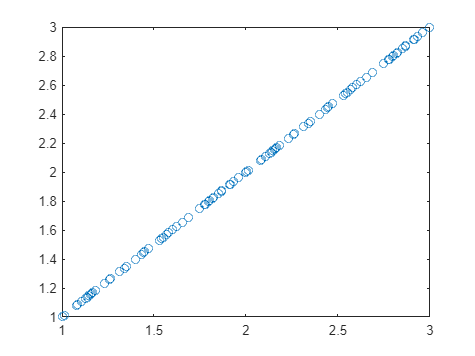

figure
plot(numbs,numbs, 'o')

numbs = round(numbs)

numbs =      3     2     2     2     3     3     2     2     2     3     2     2     2     3     2     2     1     2     3     3     1     2     2     1     2     1     2     3     1     1     3     2     2     1     2     2     2     3     1     2     3     1     1     2     2     2     3     3     2     2


[Nnumbs, Cnumbs] = unique(numbs)

Nnumbs =      1     2     3


Cnumbs =     17
     2
     1


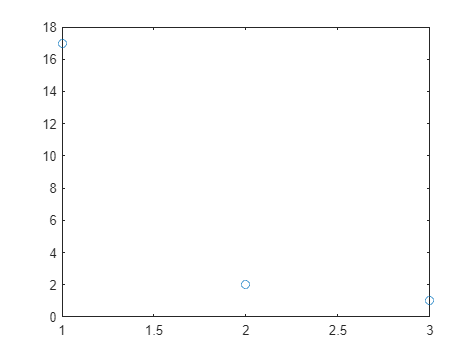

plot(Nnumbs, Cnumbs, 'o')

diffmat = numbs-numbs'

diffmat =      0    -1    -1    -1     0     0    -1    -1    -1     0    -1    -1    -1     0    -1    -1    -2    -1     0     0    -2    -1    -1    -2    -1    -2    -1     0    -2    -2     0    -1    -1    -2    -1    -1    -1     0    -2    -1     0    -2    -2    -1    -1    -1     0     0    -1    -1
     1     0     0     0     1     1     0     0     0     1     0     0     0     1     0     0    -1     0     1     1    -1     0     0    -1     0    -1     0     1    -1    -1     1     0     0    -1     0     0     0     1    -1     0     1    -1    -1     0     0     0     1     1     0     0
     1     0     0     0     1     1     0     0     0     1     0     0     0     1     0     0    -1     0     1     1    -1     0     0    -1     0    -1     0     1    -1    -1     1     0     0    -1     0     0     0     1    -1     0     1    -1    -1     0     0     0     1     1     0     0
     1     0     0     0     1     1     0     0     0     1     0     0     0     1   

A = int8(1)

A = int8
1

%A = 0;
for i = 1:400
 A = A-(i)
end

A = int8
0

A = int8
-2

A = int8
-5

A = int8
-9

A = int8
-14

A = int8
-20

A = int8
-27

A = int8
-35

A = int8
-44

A = int8
-54

A = int8
-65

A = int8
-77

A = int8
-90

A = int8
-104

A = int8
-119

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

A = int8
-128

figureName = "fig"

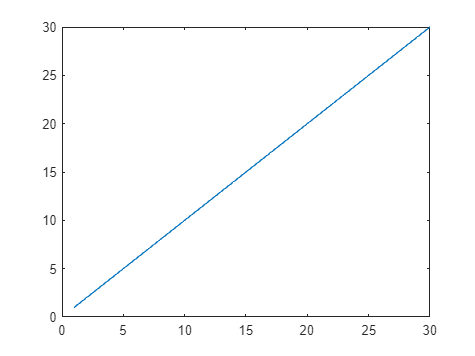

CMO_PRESENT_1D1R(testc)

figure('Name','fig')
plot(testc)

directory = 'test2/'

directory = 'test2/'

mes = 'test3'

mes = 'test3'

FN = '10_10__blabla.txt'

FN = '10_10__blabla.txt'

mkdir(join([directory, mes]))

copyfile(join([directory, FN], join([directory, mes, '/', FN])))

join([directory, mes, '/', FN])

ans = 'test2/test3/10_10__blabla.txt'

copyfile(join([directory, FN]), join([directory, mes, '/', FN]) )

x1 = [10 25 4 10 9 4 4]';
y = [10 25 4 10 9 4 4 5 5]';
[GC,GR] = groupcounts(x1)

GC =      3
     1
     2
     1


GR =      4
     9
    10
    25


G1 = [GR,GC];
[GC,GR] = groupcounts(y)

GC =      3
     2
     1
     2
     1


GR =      4
     5
     9
    10
    25


G2 = [GR,GC];
CMO_merge_groupcount(G1, G2)

ans =      4     6
     5     2
     9     2
    10     4
    25     2


[GC,GR] = groupcounts([x1;y])

GC =      6
     2
     2
     4
     2


GR =      4
     5
     9
    10
    25


clear
load TestTimeRow.mat
OPT1p2 = int64(OPT1p)

OPT1p2 = 3977×1 int64 column vector
    1049
   40517
   40527
   40537
   40547
   40557
   40567
   40577
   40587
   40597


%OPT1 = CMO_Time_overflow_corretor(OPT1p2(2:end), 65535, -OPT1p2(2))
bias = 0

bias = 0

for i = 1:size(OPT1p2,1)-1
    OPT1p2(i) = OPT1p2(i) + bias;
    if OPT1p2(i)-bias>OPT1p2(i+1)
        %OPT1p2(i+1:end) = OPT1p2(i+1:end)+bias;
        bias = bias+65535;
    end
end
OPT1p2(end) = OPT1p2(end) + bias

OPT1p2 = 3977×1 int64 column vector
    1049
   40517
   40527
   40537
   40547
   40557
   40567
   40577
   40587
   40597


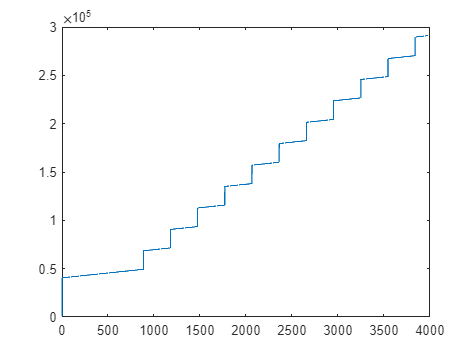

figure
plot(OPT1p2)

clear
B = 5000;
TS = 50000;
L = 10000;
SN = 20;
SK = 4000;
S2 = 10;

TR1 = CMO_Test_DataEx1(L,B,S2);
TRa = CMO_Test_DataEx2W(TR1, SN, SK);
TR2 = CMO_Test_DataEx1MM(min(TRa), max(TRa), L+1);
TRb  = CMO_Test_DataEx3W(TRa, TS);

Fun1 = @(x) 140000*sin(x/10000)+150000+5*x ;%+1300*TR13200;
Fun2 = @(x) Fun1(x)*3 -36000;

DTa = Fun1(TRa);
DT2 = Fun2(TR2);

save TestBase.mat *

clear
B = 5000;
TS = 50000

TS = 50000

L = 10000;
SN = 20;
SK = 4000;
S2 = 10;

TR1 = 0:L;
TR1 = TR1 * S2;
TR1 = TR1+B;
StepN = round(rand()*SN)

StepN = 10

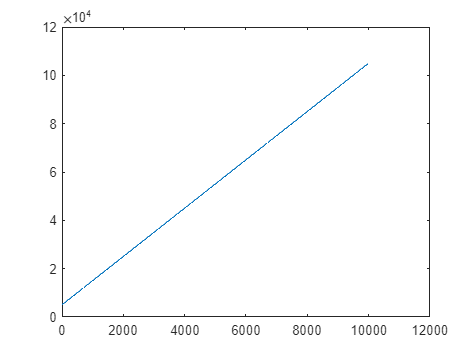

Steps = zeros(1, StepN);
for i = 1:StepN
    Steps(i) = round(rand()*L);
end
Steps = sort(unique(Steps));

figure
plot(TR1)

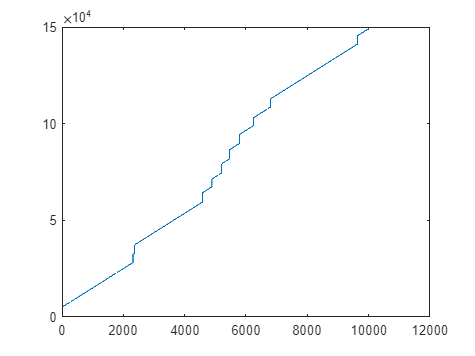

for i = Steps
    TR1(i:end) = TR1(i:end)+(rand()*SK*0.2)+SK;
end
figure
plot(TR1)

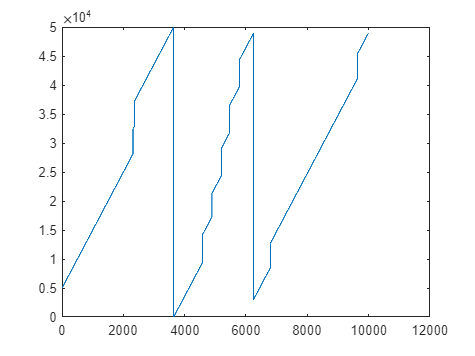

TRa = TR1;

for  i = 1:size(TR1, 2)
    if TR1(i) > TS
        TR1(i:end)=TR1(i:end)-TS;
    end
end

figure
plot(TR1)

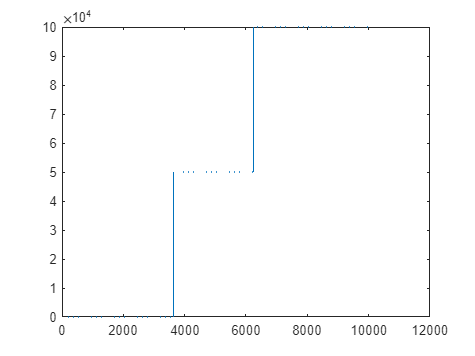


figure
plot(TRa-TR1)

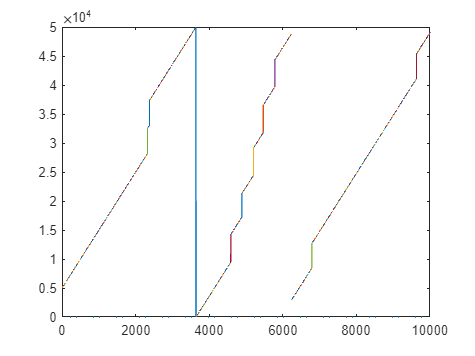


Parts = 1:20:L;
Parts = [Parts,L+1];
TRP = {};
for i = 2:size(Parts, 2)
    TRP{i-1} = TR1(Parts(i-1):Parts(i)-1);
end
figure
plot(zeros(1, L))
HL = 1:L;
p1 = 1;
p2 = 20;
hold on
for i = 1:size(TRP,2)
    plot(HL(p1:p2),TRP{i})
    p1 = p2+1;
    p2 = p2+20;
end
hold off





%bias = -B;
Tbias = TS;
Prev = 0;
TR2 = [];
TR2a = TR1;
TRW = zeros(1,L);
for j = 1:size(TR1,2)-1
    if TR1(j) > TR1(j+1)
            TR2a(j+1:end) = TR2a(j+1:end) + TS;
            TRW(j+1:end) = TRW(j+1:end) + TS;
            %Tbias = Tbias + TS;
    end
end

figure
plot(TR2a)

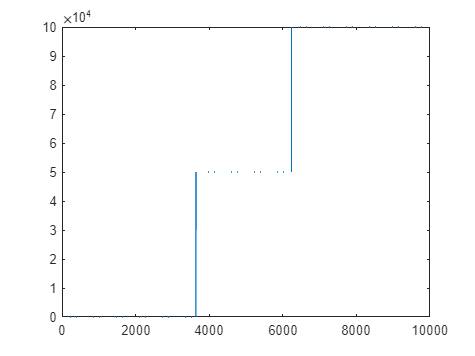

figure
plot(TRW)

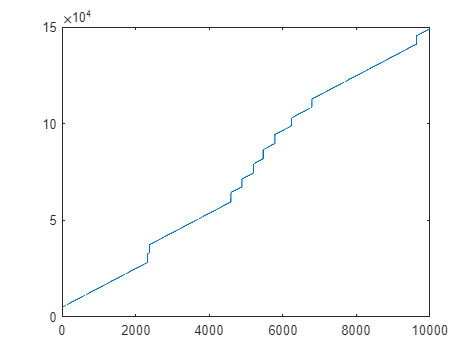


Tbias = 0;

for i = 1:size(TRP,2)
    [T, Tbias, Prev] = CMO_Time_overflow_corrector(TRP{i}', TS, Tbias, Prev);
    TR2 = [TR2,T'];

%     T = TRP{i};
%     T = [Prev, T];
%     Prev = T(end);
%     T = T + Tbias;
% 
%     for j = 1:size(T,2)-1
% 
%         if T(j) > T(j+1)
%             T(j+1:end) = T(j+1:end) + TS;
%             Tbias = Tbias + TS;
%         end
%     end
%     TR2 = [TR2,T(2:end)];

end
figure
plot(TR2)

figure
DI = TRa(1:size(TRa,2)-1)-TR2

DI =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


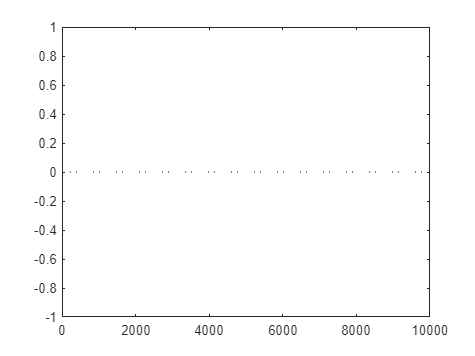

plot(DI)

clear
B = 5000;
TS = 50000

TS = 50000

L = 10000;
SN = 20;
SK = 4000;
S2 = 10;

TR1 = 0:L;
TR1 = TR1 * S2;
TR1 = TR1+B;



StepN = round(rand()*SN)

StepN = 14

Steps = zeros(1, StepN);
for i = 1:StepN
    Steps(i) = round(rand()*L);
end
Steps = sort(unique(Steps));

figure
plot(TR1)

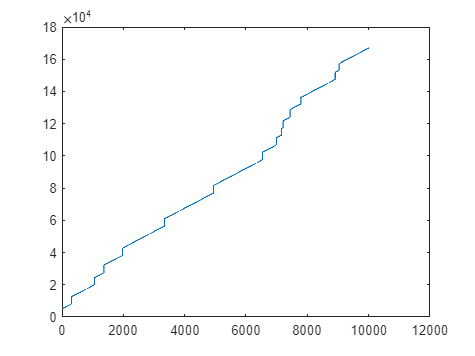

for i = Steps
    TR1(i:end) = TR1(i:end)+(rand()*SK*0.2)+SK;
end
figure
plot(TR1)

TRa = TR1;
TR1 = 0:L;
TR1 = TR1/L * (max(TRa)-min(TRa)) + min(TRa);
TR1 = round(TR1);
T = (max(TRa)-min(TRa))/(L+1)

T = 16.1864

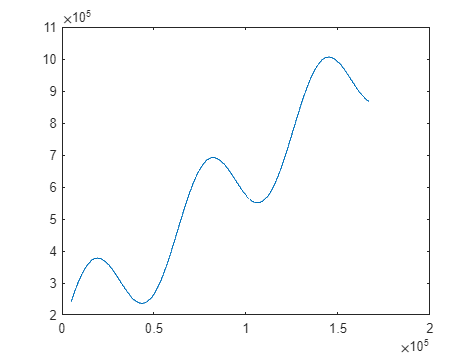

DR1 = 140000*sin(TR1/10000)+150000+5*TR1 ;%+1300*TR13200;
figure
plot(TR1, DR1)

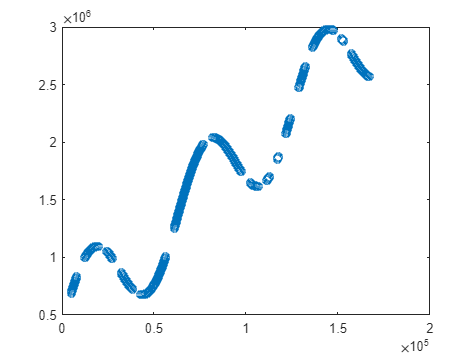

DR2 = (140000*sin(TRa/10000)+150000+ 5*TRa)*3 -36000;

for  i = 1:size(TR1, 2)
    if TR1(i) > TS
        TR1(i:end)=TR1(i:end)-TS;
    end
end
TRa = TRa';
LI = CMO_time_skip_detect(TRa,10, 0.1);
LI = LI==1;
R1 = TRa;
R1 = TRa(LI);
R2 = TRa([LI(2:end);true], 1);
Intr = zeros(max(size(R2,1),size(R1,1)+1), 2);
Intr = Intr - 2;
Intr(1:size(R1,1)+1, 1) = [B;R1];
Intr(1:size(R2,1), 2) = R2;

[RS_DR2, RS_TRa] = CMO_ResmaplePart(DR2', TRa, 1/T);
figure
plot(TRa, DR2, 'o')

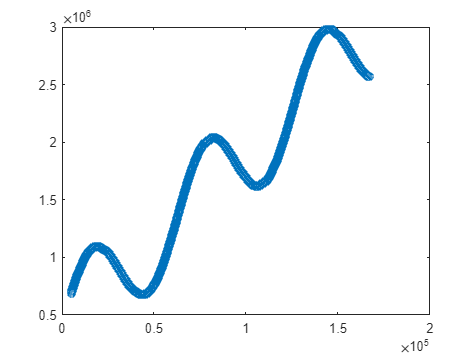

figure
plot(RS_TRa, RS_DR2, 'o')

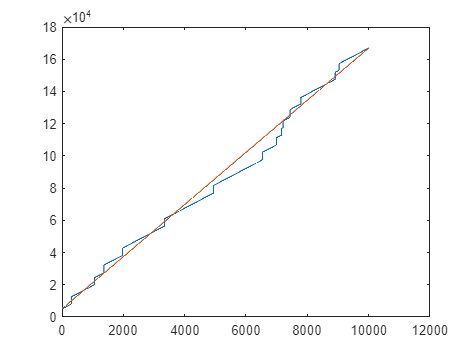

figure
plot(TRa)
hold on
plot(RS_TRa)

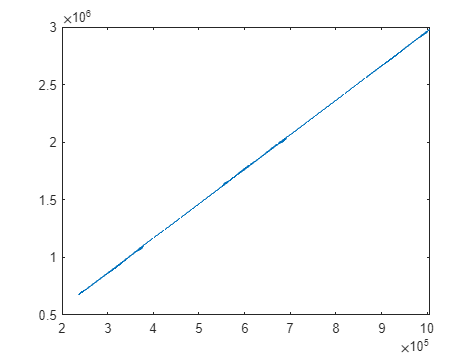


figure
plot(DR1, RS_DR2(1:end-1))

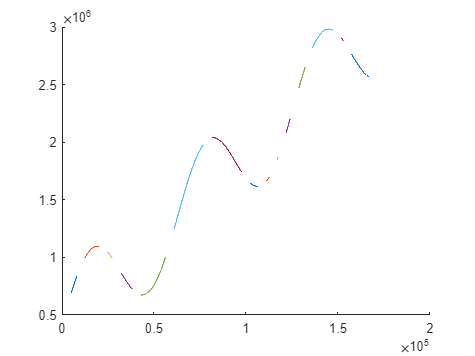


SLC = CMO_Slicing(RS_DR2,RS_TRa,Intr);

figure
hold on
for i = 1:size(SLC,2)
    plot(SLC{i}(:,1), SLC{i}(:,2))
end
hold off

save SLicing.mat *

clear
load SLicing.mat

T = (max(TRa)-min(TRa))/(L+1)

T = 16.1864

Parts = 1:200:L;
Parts = [Parts,L+1];
TRP = {};
DR2 = DR2';
for i = 2:size(Parts, 2)
    TRP{i-1} = [TRa(Parts(i-1):Parts(i)-1, 1), DR2(Parts(i-1):Parts(i)-1, 1)];
end

PLog = 1;
Bigst = 0;
prevTS = TRP{1}(1,1);
prevVS = TRP{1}(1,2);
TRP{1} = TRP{1}(2:end,:);

TRP2 = {}


TRP2 =

  0×0 empty cell array



size(TRP, 2)

ans = 50

for i = 1:size(TRP, 2)
    disp("eh");
    % time overflow correction
    
    T1 = TRP{i}(:,1);
    D1 = TRP{i}(:,2);
    Bigst = T1(end);
    % time skip detect
    LI = CMO_time_skip_detect([prevTS; T1],10, 0.1);
    % time intervals
    I = 0;
    I = sum(LI,1);
    if I>0
        sum(LI,1)
        size(LI,1)
        LI
    end
    LI = LI==1;
    LI =  LI(2:end);
    R1 = T1(LI);
    R2 = T1([LI(2:end);false], 1);
    if I>0
        R1
        R2
    end
    if size(R2,1)==0
        if size(R1, 1)==0
            Intr = [T1(1), Bigst];
        else
            Intr = [R1(1), Bigst];
        end
    elseif R1(1)>R2(1)
        Intr = [[prevTS, R2(1)]; [R1(1:end-1);R2(2:end)]; [R1(end), Bigst]];
    else
        Intr = [[0,prevTS];[R1(1:end-1);R2]; [R1(end), Bigst]];
    end
    if I>0
        Intr
    end
    
    %Intr = zeros(max(size(R2,1),size(R1,1)+1), 2);
    %Intr = Intr - 2;
    %Intr(1:size(R1,1)+1, 1) = [B;R1];
    %Intr(1:size(R2,1), 2) = R2;
    % resample
    [RS_D1, RS_T1] = CMO_Interp1Part(D1, T1, 1/T, prevVS, prevTS);
    prevTS = TRP{i}(end,1);
    LV = zeros(size(RS_T1,1),1);
    for j = 1:size(Intr,1)
        LI = RS_T1>=Intr(j,1);
        LI2 = RS_T1<=Intr(j,2);
        LI = LI & LI2;
        LV = LV + LI;
    end
    if I>0
        LV
    end
    TRP2{i} = [RS_T1, RS_D1, LV];
end

eh


Error using horzcat
Dimensions of arrays being concatenated are not consistent.

figure
hold on
for i = 1:size(TRP2,2)
    plot(TRP2{i}(TRP2{i}(:,3)==1,1), TRP2{i}(TRP2{i}(:,3)==1,2), 'o')
end
hold off

figure
hold on
for i = 1:size(TRP2,2)
    plot(TRP2{i}(:,1), TRP2{i}(:,2), 'o')
end
hold off

clear
load TestBase.mat

display('TRa')
size(TRa)
min(TRa)
max(TRa)
display('===============================')
display('DTa')
size(DTa)
min(DTa)
max(DTa)
display('===============================')
display('TR2')
size(TR2)
min(TR2)
max(TR2)
display('===============================')

R_DTa = interp1(TRa, DTa, TR2);
figure
plot(TRa)
figure
plot(TR2')
figure
plot(DTa)

figure
plot(TRa, DTa, '-o')
figure
plot(TR2, R_DTa, '-o')

clear

fun = @(x) sin(x*(2*pi)/100);

x1 = 0:2:20;
x1 = [x1, 30:5:70];
x1 = [x1, 78:100];
v = [fun(x1); fun(x1./2)];

xq = 0:3:99;
xq = xq*1.01;

display('x')
size(x1)
min(x1)
max(x1)
display('===============================')
display('v')
size(v)
min(v)
max(v)
display('===============================')
display('xq')
size(xq)
min(xq)
max(xq)
display('===============================')




figure
vq1 = interp1(x1,v,xq);
plot(x1,v,'o')
hold on
plot(xq,vq1,':.');
xlim([0 100]);
title('(Default) Linear Interpolation');
figure
plot(xq, vq1, '-o')

clear
load TestBase.mat
Part_Length = 200;
[TRP] = CMO_Test_BreakerE(TRa, DTa, Part_Length);
for i = 1:size(TRP, 2)
    TRP{i} = TRP{i}(:,[1 2 2]);
    TRP{i}(:,3) = TRP{i}(:,3)*2 - 200000;
end
prevTS = TRP{1}(1,1);
prevVS = TRP{1}(1,2:end);
TRP{1}= TRP{1}(2:end,:);
T = 30;
for i = 1:size(TRP, 2)
    T1 = TRP{i}(:,1);
    D1 = TRP{i}(:,2:end);
    Bigst = T1(end);
    % time skip detect
    LI = CMO_time_skip_detect([prevTS; T1],10, 0.1);
    [IntervalMat] = CMO_IntervalFromDetect(T1, LI(2:end), prevTS, Bigst);
    [RS_D1, RS_T1] = CMO_Interp1Part(D1, T1, 1/T, prevVS, prevTS);
    [LV] = CMO_IntervalToInclude(RS_T1, IntervalMat);
    prevTS = TRP{i}(end,1);
    prevVS = TRP{i}(end,2:end);
    TRP2{i} = [RS_T1', RS_D1, LV'];
end

figure
plot(TRa, DTa, '-o')
figure
hold on
for i = 1:size(TRP2,2)
    plot(TRP2{i}(:,1), TRP2{i}(:,2), 'o')
end
hold off

figure
hold on
for i = 1:size(TRP2,2)
    plot(TRP2{i}(TRP2{i}(:,end)==1,1), TRP2{i}(TRP2{i}(:,end)==1,2), 'o')
end
hold off

figure
hold on
for i = 1:size(TRP2,2)
    plot(TRP2{i}(:,1), TRP2{i}(:,3), 'o')
end
hold off

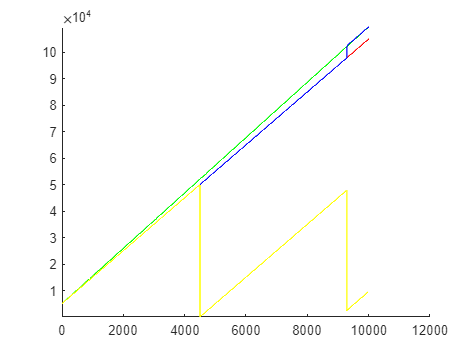

clear
load TestBase.mat

Wave = @(x, f, c, A, b, a)(A*sin(x*f+c)+a*x +b);

Norm = @(x, xmm)( ...
        (x(:, 2:end)-xmm(1,:))./(xmm(2,:)-xmm(1,:)) ...
    );

TR1 = TR1';
TR2 = TR2';
TRa = TRa';
TRb = TRb';

x1 = 1:10001;
x1 = x1';

D3d = @(x) ([Wave(x, 0.00001, 300, 30000, 30000, 1.5), Wave(x, 0.000011, 500, 20000, 50000, 1.7), Wave(x, 0.000009, 150, 50000, 20000, 1.2) ]);

AXmin = min([min(TR1), min(TR2), min(TRa), min(TRb)]);
AXmax = max([max(TR1), max(TR2), max(TRa), max(TRb)]);

figure
hold on
plot(x1, TR1, 'r', x1, TR2, 'g', x1, TRa, 'b', x1, TRb, 'y')
ylim([AXmin, AXmax])
hold off

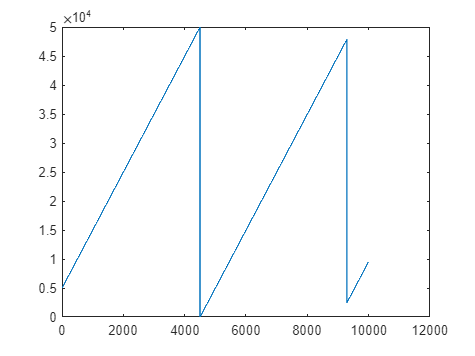


opt1 = [TRb,D3d(TRa)];
O1 = opt1;
figure
plot(x1, O1(:,1))

prevTS = opt1(1, 1);
prevVS = opt1(1, 2:end);
%opt1 = opt1(2:end, :)
op1MM = [min(opt1(:,2:end), [], 1); max(opt1(:,2:end), [], 1)]

op1MM = 1.0e+05 *

    0.0751    0.4819   -0.0813
    1.8007    2.1644    1.6093


bias = 0;
starters = min(TRa);
opt1 = opt1(2:end, :);
T = 70;

prevTS

prevTS = 5000

opt1(1,1)

ans = 5010


size(opt1)

ans =        10000           4


opt1

opt1 = 1.0e+05 *

    0.0501    0.0753    0.4820   -0.0812
    0.0502    0.0754    0.4822   -0.0810
    0.0503    0.0756    0.4823   -0.0809
    0.0504    0.0757    0.4825   -0.0807
    0.0505    0.0759    0.4826   -0.0806
    0.0506    0.0760    0.4828   -0.0804
    0.0507    0.0762    0.4829   -0.0803
    0.0508    0.0763    0.4831   -0.0801
    0.0509    0.0765    0.4832   -0.0800
    0.0510    0.0766    0.4834   -0.0798


[OUopt, EUopt, PreT, PreTN, PreV, bias] = CMO_OptProc(opt1, op1MM, bias, T, prevTS, prevVS, prevTS, starters, TS );

IntervalMat = 1.0e+05 *

         0    0.9287
    0.9746    1.0458


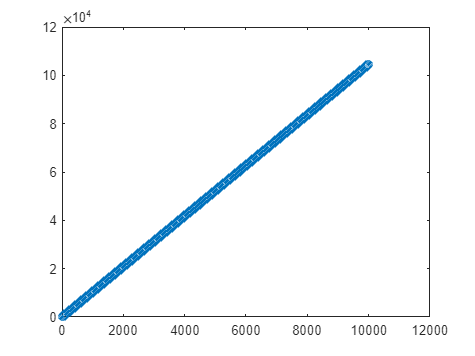

figure
xn = 1:size(OUopt(:,1), 1);
xn = xn/size(OUopt(:,1), 1) *10001;
plot(xn, OUopt(:,1), 'o')

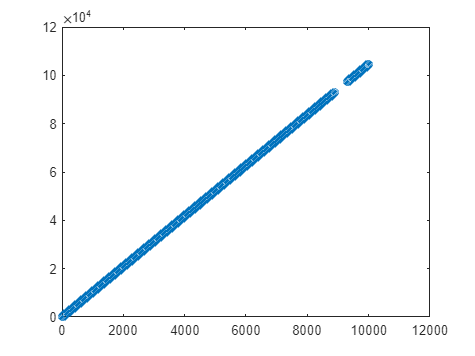


plot(xn(OUopt(:,end)==1), OUopt(OUopt(:,end)==1,1), 'o')

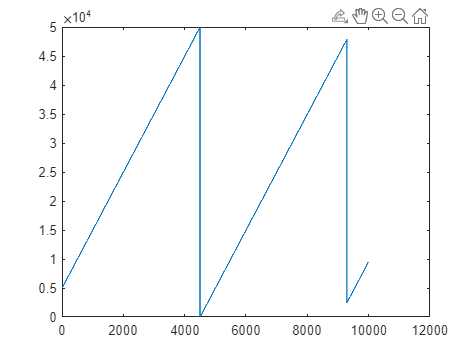

opt1(:, 2:end) = Norm(opt1, op1MM);
figure
plot(x1, O1(:,1))

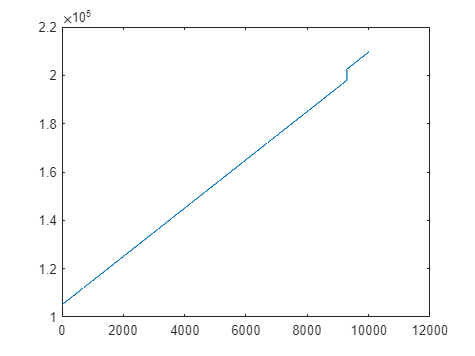

[opt1(:,1), bias(4), prevTSN] = CMO_Time_overflow_corrector(opt1(:,1), TS, bias);
figure
plot(x1(2:end), opt1(:,1))

opt1(:,1) =  opt1(:,1) - starters;
Oss1 = [PreT; opt1(:,1)];
Bigst = opt1(end,1);
TEMP1 = CMO_time_skip_detect(opt1(:,1),10, 0.1);
[OPT1Interval] = CMO_IntervalFromDetect(opt1(:,1), TEMP1, prevTS, Bigst);

IntervalMat = 1.0e+05 *

    0.0500    1.9287
    1.9746    2.0458


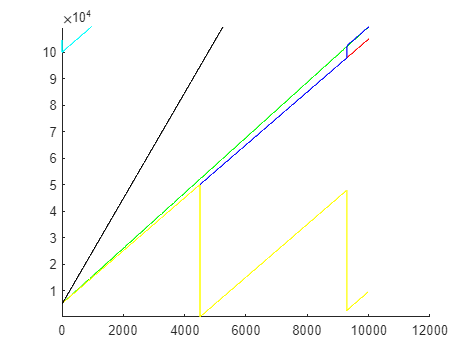

[RS_D1, RS_T1] = CMO_Interp1Part(opt1(:,2:end), opt1(:,1), 1/T, prevVS, prevTS);
[LV] = CMO_IntervalToInclude(RS_T1, OPT1Interval);
prevTS = opt1(end,1);
prevVS = opt1(end,2:end);
Oopt1 = [RS_T1', RS_D1, LV'];
EUopt1 = [CMO_Metric_Euc(RS_D1), LV'];

figure
hold on
plot(x1, TR1, 'r', x1, TR2, 'g', x1, TRa, 'b', x1, TRb, 'y', x1, Oss1, 'c')
xn = 1:size(Oopt1(:,1), 1);
xn = xn/size(Oopt1(:,1), 1) *10001;
plot(xn, Oopt1(:,1), 'k')
hold off
ylim([AXmin, AXmax])


figure
plot(TRa, opt1(:,2), 'r', TRa, opt1(:,3), 'g', TRa, opt1(:,4), 'b')

Error using plot
Vectors must be the same length.

xlim([min(TRa), max(TRa)]);
ylim([min(opt1(:,2:end), [], 'all'), max(opt1(:,2:end), [], 'all')]);

figure
plot(Oopt1(:,1), Oopt1(:,2), 'r', Oopt1(:,1), Oopt1(:,3), 'g', Oopt1(:,1), Oopt1(:,4), 'b')
xlim([min(Oopt1(:,1)), max(Oopt1(:,1))]);
ylim([min(Oopt1(:,2:end), [], 'all'), max(Oopt1(:,2:end), [], 'all')]);

figure
plot(OUopt(:,1), OUopt(:,2), 'r', OUopt(:,1), OUopt(:,3), 'g', OUopt(:,1), OUopt(:,4), 'b')
xlim([min(OUopt(:,1)), max(OUopt(:,1))]);
ylim([min(OUopt(:,2:end), [], 'all'), max(OUopt(:,2:end), [], 'all')]);

clear
Wave = @(x, f, c, A, b, a)(A*sin(x*f+c)+a*x +b);
D3d = @(x) ([Wave(x, 0.000010, 300, 30000, 30000, 1.5), ...
             Wave(x, 0.000011, 500, 20000, 50000, 1.7), ...
             Wave(x, 0.000009, 150, 50000, 20000, 1.2) ]);
ComRate = 10

ComRate = 10

ReadRate = 75

ReadRate = 75

BuffSiz = 1000

BuffSiz = 1000

L = 10200

L = 10200

Tbase = (1:L)'

Tbase =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


ComRow = [Tbase*ComRate, D3d(Tbase*ComRate) ]

ComRow = 1.0e+05 *

    0.0001    0.0002    0.4066   -0.1573
    0.0002    0.0004    0.4067   -0.1571
    0.0003    0.0005    0.4069   -0.1570
    0.0004    0.0007    0.4070   -0.1568
    0.0005    0.0008    0.4072   -0.1567
    0.0006    0.0010    0.4073   -0.1565
    0.0007    0.0011    0.4075   -0.1564
    0.0008    0.0013    0.4077   -0.1562
    0.0009    0.0014    0.4078   -0.1561
    0.0010    0.0016    0.4080   -0.1559




Parts = 0:BuffSiz:size(ComRow, 1)

Parts =            0        1000        2000        3000        4000        5000        6000        7000        8000        9000       10000


Parts = [Parts, size(ComRow, 1)]

Parts =            0        1000        2000        3000        4000        5000        6000        7000        8000        9000       10000       10200


Parts = Parts+1

Parts =            1        1001        2001        3001        4001        5001        6001        7001        8001        9001       10001       10201


BuffAm = length(Parts)

BuffAm = 12

BuffSizs = diff(Parts)

BuffSizs =         1000        1000        1000        1000        1000        1000        1000        1000        1000        1000         200


BuffTimes = BuffSizs*ComRate

BuffTimes =        10000       10000       10000       10000       10000       10000       10000       10000       10000       10000        2000



Buffers = {};

for i = 2:size(Parts, 2)
    Buffers{i-1} = [ComRow( Parts(i-1):Parts(i)-1, : )]
end

Buffers = 1×1 cell array
    {1000×4 double}


Buffers = 1×2 cell array
    {1000×4 double}    {1000×4 double}


Buffers = 1×3 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}


Buffers = 1×4 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}


Buffers = 1×5 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}


Buffers = 1×6 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}


Buffers = 1×7 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}


Buffers = 1×8 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}


Buffers = 1×9 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}


Buffers = 1×10 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}


Buffers = 1×11 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {200×4 double}


Buffers

Buffers = 1×11 cell array
    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {1000×4 double}    {200×4 double}



RRes = 0;
ReadRow = []


ReadRow =

     []



for i = 1:size(BuffTimes, 2)
    i
    ReadAm = floor((RRes+BuffTimes(i))/ReadRate)
    ReadRow = [ReadRow; Buffers{i}(1:ReadAm, :)];
    RRes = mod((RRes+BuffTimes(i)),ReadRate)
end

i = 1

ReadAm = 133

RRes = 25

i = 2

ReadAm = 133

RRes = 50

i = 3

ReadAm = 134

RRes = 0

i = 4

ReadAm = 133

RRes = 25

i = 5

ReadAm = 133

RRes = 50

i = 6

ReadAm = 134

RRes = 0

i = 7

ReadAm = 133

RRes = 25

i = 8

ReadAm = 133

RRes = 50

i = 9

ReadAm = 134

RRes = 0

i = 10

ReadAm = 133

RRes = 25

i = 11

ReadAm = 27

RRes = 0

ReadRow

ReadRow = 1.0e+05 *

    0.0001    0.0002    0.4066   -0.1573
    0.0002    0.0004    0.4067   -0.1571
    0.0003    0.0005    0.4069   -0.1570
    0.0004    0.0007    0.4070   -0.1568
    0.0005    0.0008    0.4072   -0.1567
    0.0006    0.0010    0.4073   -0.1565
    0.0007    0.0011    0.4075   -0.1564
    0.0008    0.0013    0.4077   -0.1562
    0.0009    0.0014    0.4078   -0.1561
    0.0010    0.0016    0.4080   -0.1559


clear

Wave = @(x, f, c, A, b, a)(A*sin(x*f+c)+a*x +b);
Norm = @(x, xmm)( ...
        (x(:, 2:end)-xmm(1,:))./(xmm(2,:)-xmm(1,:)) ...
    );
D3d = @(x) ([Wave(x, 0.000010, 300, 30000, 30000, 1.5), ...
             Wave(x, 0.000011, 500, 20000, 50000, 1.7), ...
             Wave(x, 0.000009, 150, 50000, 20000, 1.2) ]);
D8d = @(x) ([Wave(x, 0.0000110, 283, 40000, 23000, 1.30), ...
             Wave(x, 0.0000108, 452, 35000, 45000, 1.44), ...
             Wave(x, 0.0000095, 308, 25000, 37000, 1.65), ...
             Wave(x, 0.0000113, 200, 30000, 40000, 1.55), ...
             Wave(x, 0.0000103, 170, 37000, 26000, 1.22), ...
             Wave(x, 0.0000098, 390, 46000, 38000, 1.70), ...
             Wave(x, 0.0000106, 280, 40000, 30000, 1.35), ...
             Wave(x, 0.0000093, 210, 50000, 42000, 1.24) ]);


B = 5000;
TS = 50000;
L = 10000;
SN = 20;
SK = 4000;
S2 = 10;
S1 = 75

S1 = 75


TR1 = CMO_Test_DataEx1(L,B,S1)

TR1 =         5000        5075        5150        5225        5300        5375        5450        5525        5600        5675        5750        5825        5900        5975        6050        6125        6200        6275        6350        6425        6500        6575        6650        6725        6800        6875        6950        7025        7100        7175        7250        7325        7400        7475        7550        7625        7700        7775        7850        7925        8000        8075        8150        8225        8300        8375        8450        8525        8600        8675


TR1 = TR1'

TR1 =         5000
        5075
        5150
        5225
        5300
        5375
        5450
        5525
        5600
        5675


DR1 = D8d(TR1)

DR1 = 1.0e+06 *

    0.0418    0.0407    0.0495    0.0224    0.0467    0.0682    0.0193    0.0695
    0.0419    0.0408    0.0497    0.0225    0.0468    0.0684    0.0194    0.0696
    0.0420    0.0410    0.0498    0.0227    0.0469    0.0685    0.0195    0.0696
    0.0422    0.0411    0.0499    0.0228    0.0470    0.0687    0.0195    0.0697
    0.0423    0.0412    0.0501    0.0229    0.0472    0.0688    0.0196    0.0698
    0.0424    0.0414    0.0502    0.0231    0.0473    0.0690    0.0197    0.0698
    0.0425    0.0415    0.0504    0.0232    0.0474    0.0692    0.0197    0.0699
    0.0427    0.0416    0.0505    0.0233    0.0475    0.0693    0.0198    0.0699
    0.0428    0.0418    0.0506    0.0235    0.0476    0.0695    0.0199    0.0700
    0.0429    0.0419    0.0508    0.0236    0.0478    0.0696    0.0200    0.0701


TR2 = min(TR1):S2:max(TR1)

TR2 =         5000        5010        5020        5030        5040        5050        5060        5070        5080        5090        5100        5110        5120        5130        5140        5150        5160        5170        5180        5190        5200        5210        5220        5230        5240        5250        5260        5270        5280        5290        5300        5310        5320        5330        5340        5350        5360        5370        5380        5390        5400        5410        5420        5430        5440        5450        5460        5470        5480        5490


TR2 = TR2';
DR2 = D3d(TR2)

DR2 = 1.0e+06 *

    0.0075    0.0482   -0.0081
    0.0075    0.0482   -0.0081
    0.0075    0.0482   -0.0081
    0.0076    0.0482   -0.0081
    0.0076    0.0482   -0.0081
    0.0076    0.0483   -0.0081
    0.0076    0.0483   -0.0080
    0.0076    0.0483   -0.0080
    0.0076    0.0483   -0.0080
    0.0076    0.0483   -0.0080


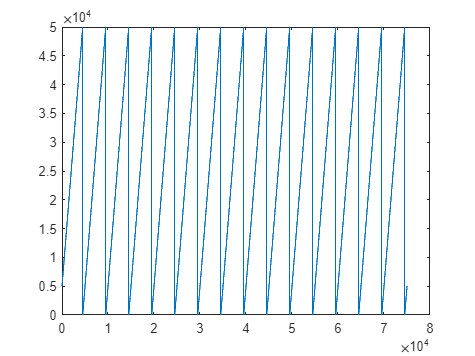

TR2C  = CMO_Test_DataEx3W(TR2, TS);
figure
plot(TR2C)

BufS = 1000;
HMS = floor(BufS*S2/S1)

HMS = 133

%{
Parts = 1:BufS:size(TR2, 1);
TRo = {};
for i = 2:size(Parts, 2)
    TRo{i-1} = [TR2C(Parts(i-1):Parts(i)-1), ...
        DR2(Parts(i-1):Parts(i)-1, :)];
end
%TRo = CMO_Test_BreakerE(TR2C, DR2, BufS)
TR2R = [];
DR2R = [];
for i = 1:size(TRo, 2)
    TR2R = [TR2R;TRo{i}(1:min(HMS, size(TRo{i}, 1)), 1)];
    DR2R = [DR2R;TRo{i}(1:min(HMS, size(TRo{i}, 1)), 2:end)];
end
%}
[ReadRow] = CMO_Test_SerialPortSim(S1, S2, BufS, [TR2C, DR2], size(TR1, 1)-1)

ComRate = 10

ReadRate = 75

BuffSiz = 1000

ReadRow = 1.0e+06 *

    0.0050    0.0075    0.0482   -0.0081
    0.0050    0.0075    0.0482   -0.0081
    0.0050    0.0075    0.0482   -0.0081
    0.0050    0.0076    0.0482   -0.0081
    0.0050    0.0076    0.0482   -0.0081
    0.0050    0.0076    0.0483   -0.0081
    0.0051    0.0076    0.0483   -0.0080
    0.0051    0.0076    0.0483   -0.0080
    0.0051    0.0076    0.0483   -0.0080
    0.0051    0.0076    0.0483   -0.0080


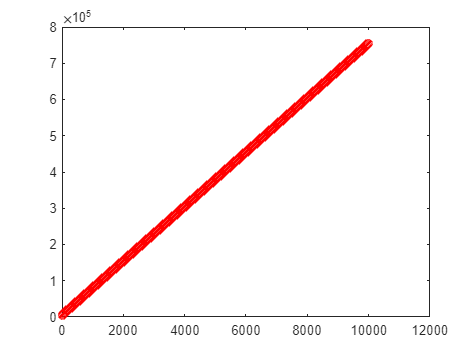

TR2R = ReadRow(:, 1);
DR2R = ReadRow(:, 2:end);
figure
x1 = 1:size(TR1, 1);
plot(x1,TR1, 'r-o')

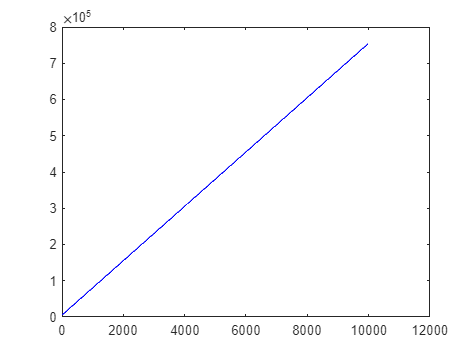

figure
x2 = 1:size(TR2,1);
x2 = x2/size(TR2,1)*size(TR1, 1);
plot(x2, TR2, 'b-')

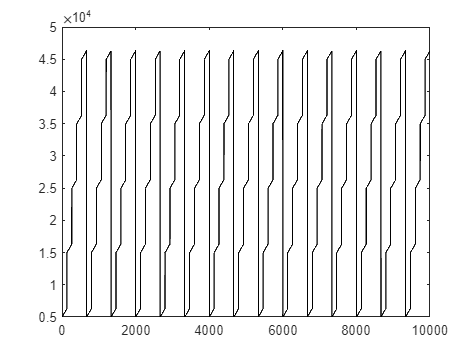

figure
x3 = 1:size(TR2R,1);
x3 = x3/size(TR2R,1)*(size(TR1, 1)-1);
plot(x3, TR2R, 'k-')


info.sensors = 2;
info.T = S1;
info.stateIND = 1;
info.movementIND = 2;
info.compT = 3;
info.myoINDt = 3;
info.myoIND = [4:11];
info.op1INDt = 12;
info.op1IND = [13:15];
info.glvTD = S1;
info.myoMM = [min(DR1, [], 1);max(DR1, [], 1)];
info.myoTD = S1;
info.op1MM = [min(DR2R, [], 1);max(DR2R, [], 1)];
info.op1TD = S2;

Tempr = [DR1(2:end, :), TR2R, DR2R];
Meas = CMO_Test_BreakerE(TR1(2:end, :), Tempr, 2000);
for i = 1: size(Meas, 2)
    Meas{i} = [ones(size(Meas{i}, 1), 1)*i, ones(size(Meas{i}, 1), 1), Meas{i}];
end

OTS1 = [];
OTS4 = [];

%==================================================================
T = info.T;
bias = zeros(1,info.sensors+1);
data = Meas{1};
    
        data = data(2:end, :);
        starters(1:3) = data(1,[info.compT, info.myoINDt, info.op1INDt]);

    
    [guide] = data(:, [info.stateIND, info.movementIND, info.compT])

guide =            1           1        5150
           1           1        5225
           1           1        5300
           1           1        5375
           1           1        5450
           1           1        5525
           1           1        5600
           1           1        5675
           1           1        5750
           1           1        5825


    %[guide] = CMO_only_change_timestamp(data(:, [info.stateIND, info.movementIND, info.compT]), [1,2], 3);
    % normalise on min-max
    myo = data(:, [info.myoINDt, info.myoIND]);
    op1 = data(:, [info.op1INDt, info.op1IND]);

    prevTS1 = [guide(1,3), myo(1,1), op1(1,1)];
    prevTS2 = prevTS1;
    prevTS4 = prevTS1;
    prevVS = {guide(1,1:2), myo(1, 2:end), op1(1, 2:end)};

    myo = myo(2:end, :);
    op1 = op1(2:end, :);
    OTS1 = op1(:,1)

OTS1 =         5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090
        5100
        5110



    %From here it's almost the same

    myo(:, 2:end) = Norm(myo, info.myoMM);
    
    prevTS1(1:2) = [guide(end,3), myo(end,1)];
    guide(:,3) = guide(:,3) - starters(1);
    myo(:,1) =  myo(:,1) - starters(2);
    %difference
    prevTS3(1) = prevTS2(1) - starters(1);
    prevTS3(2) = prevTS2(2) - starters(2);
    prevTS3(3) = prevTS2(3) - starters(3);
    prevTS4 = prevTS3;

    COMP = [myo(:,1), myo(:,2:end)];

    [RS_DC, RS_TC] = CMO_Interp1Part(COMP(:,2:end), COMP(:,1), 1/T, [prevVS{2}], prevTS4(2));
    RS_TC = RS_TC';
    OUmyo = [RS_TC, RS_DC(:,:)];
    EUmyo = [RS_TC, CMO_Metric_Euc(OUmyo(:,2:end))];

    prevVS{2} = OUmyo(end, 2:end);
    prevTS4(2) = OUmyo(end, 1);

        %                                                                    CMO_OptProc(opt, optMM,         Bias,    T, PreT1,      PreT3,      PreT4,      PreV,         Starter,        TypeSize )
    [OUop1, EUop1, prevTS1(3), prevTS3(3), prevTS4(3), prevVS{3}, bias(3)] = CMO_OptProc(op1, info.op1MM,    bias(3), T, prevTS1(3), prevTS3(3), prevTS4(3), prevVS{3},    starters(3),    TS);

IntervalMat =            0        1310


IntervalMat =            0        1310
        9990       11310
       19990       21320
       29990       31310
       39990       41310
       49990       51320
       59990       61310
       69990       71310
       79990       81320
       89990       91310


IntervalMat =            0        1310
        9990       11310
       19990       21320
       29990       31310
       39990       41310
       49990       51320
       59990       61310
       69990       71310
       79990       81320
       89990       91310


    OTS4 = OUop1;
    prevTS4(1) = guide(end,3);
    prevTS3(1:2) = [guide(end,3), myo(end,1)];
    prevVS{1} = guide(end,1:2);
    % difference
    EUO1 = EUop1

EUO1 = 1.0e+05 *

         0    0.4946    0.0000
    0.0008    0.0000    0.0000
    0.0015    0.0000    0.0000
    0.0022    0.0000    0.0000
    0.0030    0.0000    0.0000
    0.0037    0.0000    0.0000
    0.0045    0.0000    0.0000
    0.0053    0.0000    0.0000
    0.0060    0.0000    0.0000
    0.0067    0.0000    0.0000


    EUM = EUmyo;
    OUop1

OUop1 = 1.0e+05 *

         0    0.0753    0.4820   -0.0812    0.0000
    0.0008    0.0000    0.0000    0.0000    0.0000
    0.0015    0.0000    0.0000    0.0000    0.0000
    0.0022    0.0000    0.0000    0.0000    0.0000
    0.0030    0.0000    0.0000    0.0000    0.0000
    0.0037    0.0000    0.0000    0.0000    0.0000
    0.0045    0.0000    0.0000    0.0000    0.0000
    0.0053    0.0000    0.0000    0.0000    0.0000
    0.0060    0.0000    0.0000    0.0000    0.0000
    0.0067    0.0000    0.0000    0.0000    0.0000


    if sort(EUO1) ~=EUO1
        display('somehow EUop1 is not acending in the first time')
    end
    if sort(OUop1) ~= OUop1
        display('somehow OUop1 is not acending in the first time')
    end
    for i = 2:size(Meas, 2)
        i
        prevTS1
        prevTS3
        prevTS4
        EUO1
     
        
        data = Meas{i}
        [guide] = data(:, [info.stateIND, info.movementIND, info.compT])
        %[guide] = CMO_only_change_timestamp(data(:, [info.stateIND, info.movementIND, info.compT]), [1,2], 3);
    
        % normalise on min-max

        myo = data(:, [info.myoINDt, info.myoIND]);
        op1 = data(:, [info.op1INDt, info.op1IND]);
        OTS1 = [OTS1;op1(:,1)]
        myo(:, 2:end) = Norm(myo, info.myoMM);


        prevTS1(1:2) = [guide(end,3), myo(end,1)];
        guide(:,3) = guide(:,3) - starters(1);
        myo(:,1) =  myo(:,1) - starters(2);
    
        COMP = [myo(:,1),myo(:,2:end)];
        [RS_DC, RS_TC] = CMO_Interp1Part(COMP(:,2:end), COMP(:,1), 1/T, [prevVS{2}], prevTS4(2));
        RS_TC = RS_TC';
        OUmyo = [RS_TC, RS_DC(:,:)];
        EUmyo = [RS_TC, CMO_Metric_Euc(OUmyo(:,2:end))];
    
        prevVS{2} = OUmyo(end, 2:end);
        prevTS4(2) = OUmyo(end, 1);
        op1(:,1)
        prevTS1(3)
        prevTS3(3)
        prevTS4(3)
        [OUop1, EUop1, prevTS1(3), prevTS3(3), prevTS4(3), prevVS{3}, bias(3)] = CMO_OptProc(op1, info.op1MM, bias(3), T, prevTS1(3), prevTS3(3), prevTS4(3), prevVS{3},  starters(3),   TS);
        OTS4 = [OTS4; OUop1];
        prevTS4(1) = guide(end,3);
        prevTS3(1:2) = [guide(end,3), myo(end,1)];
        prevVS{1} = guide(end,1:2);
        if EUO1(end,1) > EUop1(1,1)
            display('somehow its not acending')
        end
            
        EUO1 = [EUO1; EUop1];
        EUM = [EUM; EUmyo];
   
    end

i = 2

prevTS1 =       155000      155000       46330


prevTS3 =       149850      149850       41320


prevTS4 =       149850      149850      141300


EUO1 = 1.0e+05 *

         0    0.4946    0.0000
    0.0008    0.0000    0.0000
    0.0015    0.0000    0.0000
    0.0022    0.0000    0.0000
    0.0030    0.0000    0.0000
    0.0037    0.0000    0.0000
    0.0045    0.0000    0.0000
    0.0053    0.0000    0.0000
    0.0060    0.0000    0.0000
    0.0067    0.0000    0.0000


data = 1.0e+05 *

    0.0000    0.0000    1.5508    2.6157    3.0189    3.1787    2.9947    2.4955    3.4415    2.0371    1.9346    0.0500    2.6121    2.9723    2.3417
    0.0000    0.0000    1.5515    2.6165    3.0201    3.1799    2.9961    2.4963    3.4426    2.0383    1.9354    0.0501    2.6123    2.9725    2.3419
    0.0000    0.0000    1.5522    2.6174    3.0212    3.1811    2.9974    2.4971    3.4438    2.0394    1.9361    0.0502    2.6125    2.9727    2.3420
    0.0000    0.0000    1.5530    2.6182    3.0224    3.1823    2.9988    2.4979    3.4449    2.0406    1.9368    0.0503    2.6127    2.9729    2.3422
    0.0000    0.0000    1.5537    2.6191    3.0236    3.1836    3.0002    2.4987    3.4461    2.0417    1.9375    0.0504    2.6129    2.9731    2.3424
    0.0000    0.0000    1.5545    2.6199    3.0247    3.1848    3.0015    2.4995    3.4472    2.0429    1.9383    0.0505    2.6130    2.9733    2.3425
    0.0000    0.0000    1.5553    2.6208    3.0259    3.1860    3.0029    2.

guide =            2           1      155075
           2           1      155150
           2           1      155225
           2           1      155300
           2           1      155375
           2           1      155450
           2           1      155525
           2           1      155600
           2           1      155675
           2           1      155750


OTS1 =         5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090
        5100
        5110


ans =         5000
        5010
        5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090


ans = 46330

ans = 41320

ans = 141300

IntervalMat =       149990      151310
      159990      161310
      169990      171320
      179990      181310
      189990      191310
      199990      201320
      209990      211310
      219990      221310
      229990      231320
      239990      241310


IntervalMat =       149990      151310
      159990      161310
      169990      171320
      179990      181310
      189990      191310
      199990      201320
      209990      211310
      219990      221310
      229990      231320
      239990      241310


i = 3

prevTS1 =       305000      305000       46330


prevTS3 =       299850      299850       41320


prevTS4 =       299850      299850      291300


EUO1 = 1.0e+05 *

         0    0.4946    0.0000
    0.0008    0.0000    0.0000
    0.0015    0.0000    0.0000
    0.0022    0.0000    0.0000
    0.0030    0.0000    0.0000
    0.0037    0.0000    0.0000
    0.0045    0.0000    0.0000
    0.0053    0.0000    0.0000
    0.0060    0.0000    0.0000
    0.0067    0.0000    0.0000


data = 1.0e+05 *

    0.0000    0.0000    3.0507    4.0145    4.9250    5.4335    5.3345    3.8534    5.4344    4.6069    3.8474    0.0500    5.1731    5.8139    4.3247
    0.0000    0.0000    3.0515    4.0152    4.9258    5.4346    5.3355    3.8541    5.4354    4.6082    3.8485    0.0501    5.1732    5.8141    4.3249
    0.0000    0.0000    3.0522    4.0159    4.9266    5.4357    5.3365    3.8547    5.4364    4.6095    3.8497    0.0502    5.1734    5.8142    4.3250
    0.0000    0.0000    3.0530    4.0165    4.9274    5.4367    5.3374    3.8554    5.4373    4.6108    3.8509    0.0503    5.1735    5.8144    4.3251
    0.0000    0.0000    3.0537    4.0172    4.9282    5.4378    5.3384    3.8560    5.4383    4.6121    3.8521    0.0504    5.1737    5.8146    4.3252
    0.0000    0.0000    3.0545    4.0179    4.9290    5.4388    5.3394    3.8567    5.4392    4.6134    3.8532    0.0505    5.1738    5.8148    4.3253
    0.0000    0.0000    3.0553    4.0186    4.9298    5.4399    5.3404    3.

guide =            3           1      305075
           3           1      305150
           3           1      305225
           3           1      305300
           3           1      305375
           3           1      305450
           3           1      305525
           3           1      305600
           3           1      305675
           3           1      305750


OTS1 =         5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090
        5100
        5110


ans =         5000
        5010
        5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090


ans = 46330

ans = 41320

ans = 291300

IntervalMat =       299990      301310
      309990      311310
      319990      321320
      329990      331310
      339990      341310
      349990      351320
      359990      361310
      369990      371310
      379990      381320
      389990      391310


IntervalMat =       299990      301310
      309990      311310
      319990      321320
      329990      331310
      339990      341310
      349990      351320
      359990      361310
      369990      371310
      379990      381320
      389990      391310


i = 4

prevTS1 =       455000      455000       46330


prevTS3 =       449850      449850       41320


prevTS4 =       449850      449850      441300


EUO1 = 1.0e+05 *

         0    0.4946    0.0000
    0.0008    0.0000    0.0000
    0.0015    0.0000    0.0000
    0.0022    0.0000    0.0000
    0.0030    0.0000    0.0000
    0.0037    0.0000    0.0000
    0.0045    0.0000    0.0000
    0.0053    0.0000    0.0000
    0.0060    0.0000    0.0000
    0.0067    0.0000    0.0000


data = 1.0e+06 *

    0.0000    0.0000    0.4551    0.5805    0.6659    0.7637    0.7212    0.5462    0.7665    0.6793    0.6347    0.0050    0.7180    0.8377    0.5582
    0.0000    0.0000    0.4551    0.5806    0.6660    0.7639    0.7213    0.5463    0.7666    0.6794    0.6348    0.0050    0.7180    0.8377    0.5582
    0.0000    0.0000    0.4552    0.5807    0.6661    0.7640    0.7214    0.5464    0.7667    0.6794    0.6349    0.0050    0.7180    0.8378    0.5582
    0.0000    0.0000    0.4553    0.5808    0.6662    0.7641    0.7215    0.5465    0.7669    0.6795    0.6351    0.0050    0.7180    0.8378    0.5582
    0.0000    0.0000    0.4554    0.5810    0.6663    0.7642    0.7216    0.5466    0.7670    0.6796    0.6352    0.0050    0.7181    0.8378    0.5582
    0.0000    0.0000    0.4555    0.5811    0.6664    0.7643    0.7217    0.5467    0.7671    0.6797    0.6353    0.0050    0.7181    0.8378    0.5582
    0.0000    0.0000    0.4555    0.5812    0.6665    0.7645    0.7218    0.

guide =            4           1      455075
           4           1      455150
           4           1      455225
           4           1      455300
           4           1      455375
           4           1      455450
           4           1      455525
           4           1      455600
           4           1      455675
           4           1      455750


OTS1 =         5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090
        5100
        5110


ans =         5000
        5010
        5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090


ans = 46330

ans = 41320

ans = 441300

IntervalMat =       449990      451310
      459990      461310
      469990      471320
      479990      481310
      489990      491310
      499990      501320
      509990      511310
      519990      521310
      529990      531320
      539990      541310


IntervalMat =       449990      451310
      459990      461310
      469990      471320
      479990      481310
      489990      491310
      499990      501320
      509990      511310
      519990      521310
      529990      531320
      539990      541310


i = 5

prevTS1 =       605000      605000       46330


prevTS3 =       599850      599850       41320


prevTS4 =       599850      599850      591300


EUO1 = 1.0e+05 *

         0    0.4946    0.0000
    0.0008    0.0000    0.0000
    0.0015    0.0000    0.0000
    0.0022    0.0000    0.0000
    0.0030    0.0000    0.0000
    0.0037    0.0000    0.0000
    0.0045    0.0000    0.0000
    0.0053    0.0000    0.0000
    0.0060    0.0000    0.0000
    0.0067    0.0000    0.0000


data = 1.0e+06 *

    0.0000    0.0000    0.6051    0.8331    0.9115    1.0254    0.9633    0.7752    1.0707    0.8267    0.8378    0.0050    0.9085    1.0634    0.6961
    0.0000    0.0000    0.6051    0.8333    0.9116    1.0255    0.9634    0.7754    1.0709    0.8267    0.8379    0.0050    0.9085    1.0634    0.6961
    0.0000    0.0000    0.6052    0.8334    0.9118    1.0257    0.9636    0.7755    1.0710    0.8268    0.8379    0.0050    0.9085    1.0634    0.6961
    0.0000    0.0000    0.6053    0.8335    0.9119    1.0258    0.9637    0.7756    1.0712    0.8269    0.8380    0.0050    0.9085    1.0634    0.6961
    0.0000    0.0000    0.6054    0.8336    0.9120    1.0259    0.9638    0.7757    1.0714    0.8270    0.8381    0.0050    0.9085    1.0634    0.6961
    0.0000    0.0000    0.6055    0.8338    0.9122    1.0261    0.9640    0.7758    1.0715    0.8270    0.8382    0.0050    0.9085    1.0634    0.6962
    0.0000    0.0000    0.6055    0.8339    0.9123    1.0262    0.9641    0.

guide =            5           1      605075
           5           1      605150
           5           1      605225
           5           1      605300
           5           1      605375
           5           1      605450
           5           1      605525
           5           1      605600
           5           1      605675
           5           1      605750


OTS1 =         5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090
        5100
        5110


ans = 1999×1
        5000
        5010
        5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090


ans = 46330

ans = 41320

ans = 591300

IntervalMat = 14×2
      599990      601310
      609990      611310
      619990      621320
      629990      631310
      639990      641310
      649990      651320
      659990      661310
      669990      671310
      679990      681320
      689990      691310


IntervalMat = 15×2
      599990      601310
      609990      611310
      619990      621320
      629990      631310
      639990      641310
      649990      651320
      659990      661310
      669990      671310
      679990      681320
      689990      691310


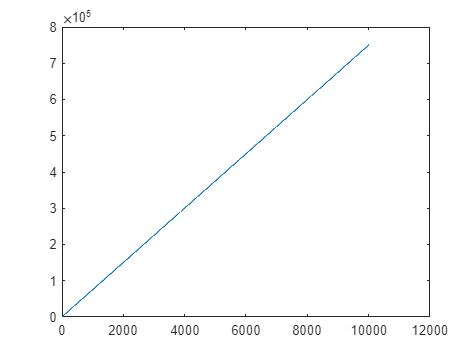

figure
plot(EUM(:,1))

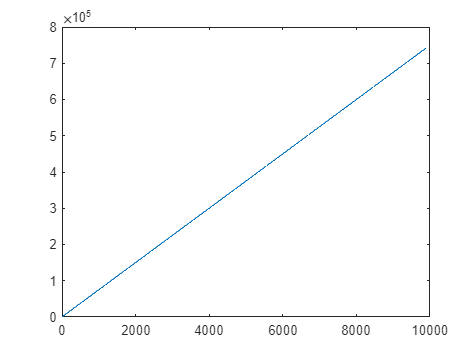

figure
plot(EUO1(:,1))

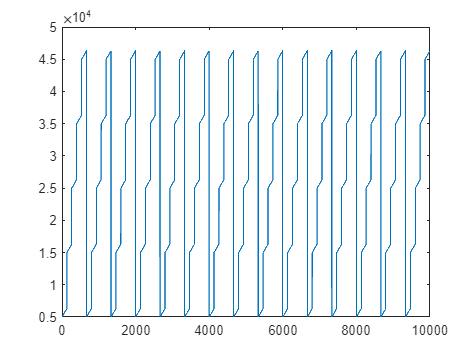

figure
plot(OTS1)

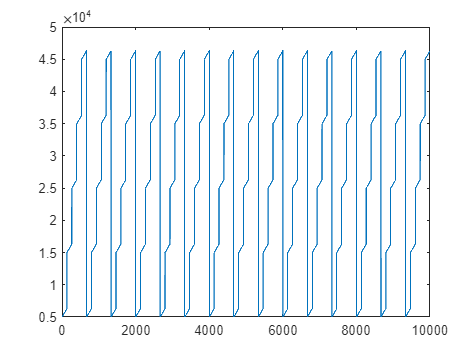

figure
plot(TR2R)

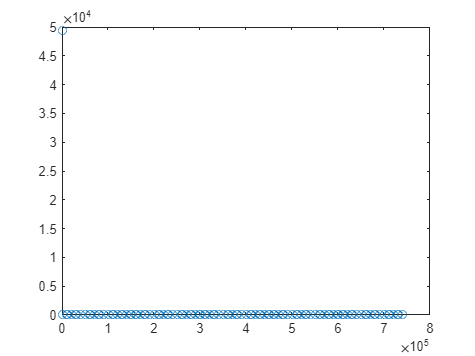


figure
plot(EUO1(EUO1(:,3)==1, 1), EUO1(EUO1(:,3)==1, 2), 'o')

[EUO1(EUO1(:,3)==1, 1), EUO1(EUO1(:,3)==1, 2)]

ans = 1325×2
1.0e+05 *

         0    0.4946
    0.0008    0.0000
    0.0015    0.0000
    0.0022    0.0000
    0.0030    0.0000
    0.0037    0.0000
    0.0045    0.0000
    0.0053    0.0000
    0.0060    0.0000
    0.0067    0.0000



[TR2R, ~, ~] = CMO_Time_overflow_corrector(TR2R, TS, 0, 0)

TR2R = 10000×1
        5000
        5010
        5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090


[TR2C, ~, ~] = CMO_Time_overflow_corrector(TR2C, TS, 0, 0)

TR2C = 75001×1
        5000
        5010
        5020
        5030
        5040
        5050
        5060
        5070
        5080
        5090


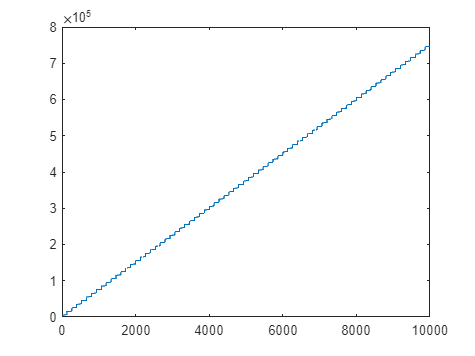

figure
plot(TR2R)


LI = CMO_time_skip_detect(TR2R,10, 0.1);
Interval = CMO_IntervalFromDetect(TR2R, LI, 0, TR2R(end,1));

IntervalMat = 1×2
           0        6320


IntervalMat = 74×2
           0        6320
       15000       16320
       25000       26330
       35000       36320
       45000       46320
       55000       56330
       65000       66320
       75000       76320
       85000       86330
       95000       96320


IntervalMat = 75×2
           0        6320
       15000       16320
       25000       26330
       35000       36320
       45000       46320
       55000       56330
       65000       66320
       75000       76320
       85000       86330
       95000       96320


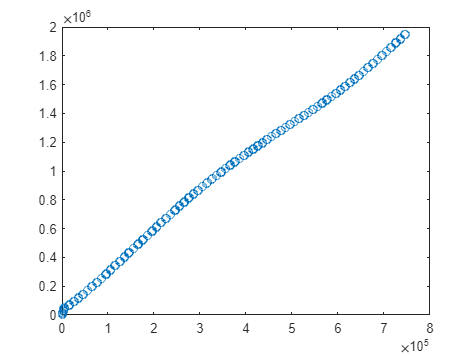

[RS_D1, RS_T1] = CMO_Interp1Part(DR2R, TR2R, 1/T, [0 0 0], 0);
[LV] = CMO_IntervalToInclude(RS_T1, Interval);
EUC = CMO_Metric_Euc(RS_D1);
figure
plot(RS_T1(LV==1), EUC(LV==1), 'o')

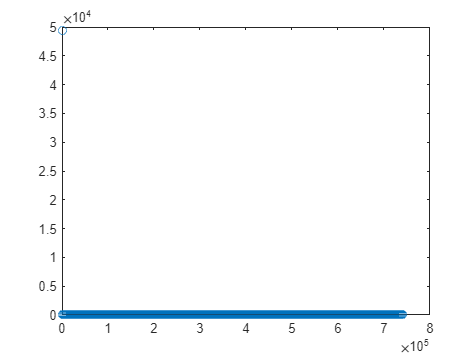


figure
plot(EUO1(:, 1), EUO1(:, 2), 'o')

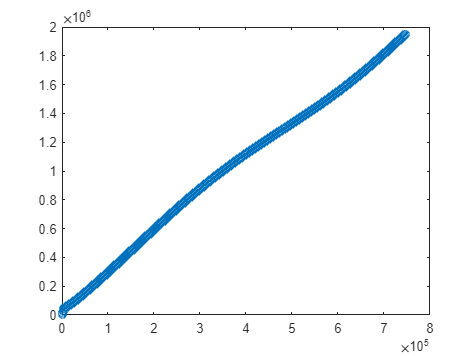


figure
plot(RS_T1, EUC, 'o')

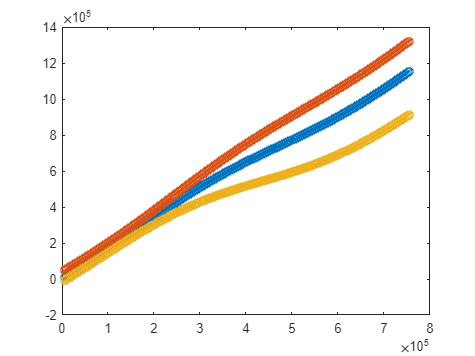


figure
plot(TR2, DR2, 'o')

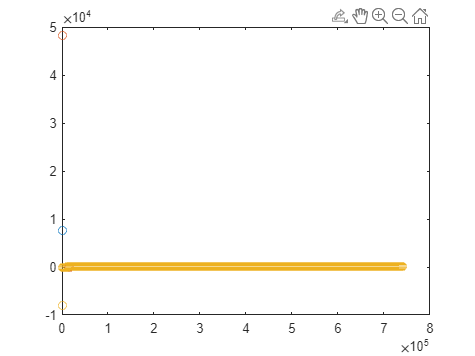


figure
plot(OTS4(:, 1), OTS4(:, 2:4), 'o')

clear
dataE = zeros(65000, 49)

dataE =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

clear

L1 = (1:100)';
L1 = [L1; (99:80)'];
L2 = (1:80)';
L2 = [L2; (81:0.1:90)'];

size(L1)

ans =    100     1


size(L2)

ans =    171     1




LI1 = zeros(length(L1), 1);
LI1(1:32) = 1;
LI1(73:end) = 1;
LI1(45:62) = 1;
LI1 = LI1==1;

m = min(length(L1), length(L2));
Lo = [L1(1:m), L2(1:m)]

Lo =      1     1
     2     2
     3     3
     4     4
     5     5
     6     6
     7     7
     8     8
     9     9
    10    10


len = round(m/10)

len = 10

Parts = 1:len:m;
L = {};
for i = 2:size(Parts, 2)

    L{i-1} = [Lo(Parts(i-1):Parts(i)-1, :)];
end
L

L = 1×9 cell array
    {10×2 double}    {10×2 double}    {10×2 double}    {10×2 double}    {10×2 double}    {10×2 double}    {10×2 double}    {10×2 double}    {10×2 double}



CMO_SepByLindex(L1, LI1);

List = 1×3 cell array
    {32×1 double}    {18×1 double}    {28×1 double}



Lr1 = rand(m,1)

Lr1 =     0.8805
    0.9245
    0.0813
    0.4827
    0.1283
    0.2529
    0.8840
    0.1963
    0.1214
    0.5437


Lr2 = rand(m,1)

Lr2 =     0.1884
    0.0229
    0.4494
    0.2436
    0.8687
    0.5286
    0.9141
    0.9739
    0.5854
    0.1190


Lor = [Lr1, Lr2];
Li1 = {};
for i = 2:size(Parts, 2)
    Li1{i-1} = [Lor(Parts(i-1):Parts(i)-1, :)];
end
n = 0;
InL = {};
AE = 0;
ind = 1;
while n<m
    Am = 1:ceil(rand()*len+2);
    Am = Am + AE;
    n = n+length(Am);
    if n>m
        Am = Am(1:length(Am)-n+m);
        InL{ind} = Am;
        break;
    end
    InL{ind} = Am;
    AE = Am(end);
    ind = ind+1;
end
for i = 1:length(InL)
    LRan{i} = Lor(InL{i},:);
end
LRan

LRan = 1×14 cell array
    {11×2 double}    {9×2 double}    {4×2 double}    {8×2 double}    {4×2 double}    {12×2 double}    {3×2 double}    {6×2 double}    {8×2 double}    {7×2 double}    {11×2 double}    {8×2 double}    {5×2 double}    {4×2 double}



R = CMO_ListCORRCheck(L)

method = 'mean'

Mean = function_handle with value:
    @(x,l)(mean(x,'all'))


R = 1

R = CMO_ListCORRCheck(LRan)

method = 'mean'

Mean = function_handle with value:
    @(x,l)(mean(x,'all'))


R = 0.0175

R = CMO_ListCORRCheck(LRan, 'weightedmean')

Mean = function_handle with value:
    @(x,l)(sum(x.*l,'all')/(sum(ones(length(x),1).*l,'all')))


R = 0.0175

clear

L1 = (1:100)';
L1 = [L1; (99:80)'];
L2 = rand(size(L1, 1), 1);

LI1 = zeros(length(L1), 1);
LI1(1:32) = 1;
LI1(73:end) = 1;
LI1(45:62) = 1;
LI1 = LI1==1;

L = CMO_SepByLindex([L1,L2], LI1)

List = 1×3 cell array
    {32×2 double}    {18×2 double}    {28×2 double}


L = 1×3 cell array
    {32×2 double}    {18×2 double}    {28×2 double}


R = CMO_ListCORRCheck(L)

method = 'mean'

Mean = function_handle with value:
    @(x,l)(mean(x,'all'))


R = 0.0624

clear
L1 = ones(100, 1)

L1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


L2 = rand(size(L1, 1), 1);

[r, t] = corrcoef(L1, L2)

r =    NaN   NaN
   NaN     1


t =    NaN   NaN
   NaN     1


corr(L1, L2)

ans = NaN

corr2(L1, L2)

ans = NaN

clear
R = rand(10,1);
L = ceil(rand(10,1)*10);
R = R';
L = L';
Mean = @(x, l) (mean(x,'all'))

Mean = function_handle with value:
    @(x,l)(mean(x,'all'))


Mean2 = @(x, l) ( sum(x.*l, 'all') / (sum( ones(length(x), 1).*l, 'all') ) )

Mean2 = function_handle with value:
    @(x,l)(sum(x.*l,'all')/(sum(ones(length(x),1).*l,'all')))



Mean(R, L)

ans = 0.4470

Mean2(R, L)

ans = 0.0349

clear

A = [ true, false, true, true]

A = 1×4 logical array
   1   0   1   1


B = [ false, true, true, false]'

B = 4×1 logical array
   0
   1
   1
   0


A&B

ans = 4×4 logical array
   0   0   0   0
   1   0   1   1
   1   0   1   1
   0   0   0   0


clear
hs = 9;
stepmin = 10;
All = @(x) (x*60*60*1000/stepmin);
TRY = All(hs);


%correlation by part
% collect the correlation (with euc metric) on every part (loaded the prev
% and the next and we shift it by some amount of time.

clear
interp
resample
interp1

clear
a = 1:10;
a = a';
a = [a,a*2];
a = zeros(10,2,2);
a(:,1,1)= (1:10)';
a(:,2,1)= (1:10)'*2;
a(:,1,2)= (1:10)'*2;
a(:,2,2)= (1:10)'*3;
a(1:end-1, :)

clear
metric = @(x) (CMO_Metric_Euc(x));
PA = rand(1, 5)*2;
PB = rand(1, 5)*2;
D1 = abs(PA-PB);
D1 = D1*D1';
D1 = sqrt(D1);

D2 = distance(PA, PB, metric);
D1
D2

clear
Mins = [0.2 0.2 0.2 0.2 0.2];
Maxs = [0.7 0.7 0.7 0.7 0.7];
PA = [0.5 0.5 0.5 0.5 0.5];
CMO_SimplePInHBCheck(PA, Mins, Maxs)

clear
HB.mins = [0.2 0.2 0.2 0.2 0.2];
HB.maxs = [0.7 0.7 0.7 0.7 0.7];
PA = [0.5 0.5 0.5 0.5 0.5]
HB.Pcheck = @(x)(CMO_SimplePInHBCheck(x, HB.mins, HB.maxs));
HB.Pcheck(PA)
HB.maxs = [0.4 0.7 0.7 0.7 0.7];
HB.Pcheck(PA)

clear
PA = 0:4;
List{1} = 5:9;
List{2} = 10:14;
List{3} = 15:19;
List{4} = 20:24;

AL = [4,2,3,1]

ST.A = AL;
ST.L = List;
ST.Access = @(x)(ST.L(ST.A(x)));




%[hand,q2] = CreateHand();
hand = SGhuman24DoF;
q2
%       11  12  13  14, 20  21  22  23  24, 30  31  32  33  34, 40  41  42  43  44, 50  51  52  53  54
qdeg = [20,  0,  0,  0,  0,  0, 20, 20, 20,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0]
hand = MoveHand(hand,qdeg);
HandPlot(hand, 1, [-60,30], [-100,50, 0, 200])

clear
[hand1, dhpar{1}, base{1}] = OWN_human20DOF
HandPlot(hand1, 1, [-60,30], [-100,50, 0, 200])

[hand2, dhpar{2}, base{2}] = SGhuman24DoF
HandPlot(hand2, 1, [-60,30], [-100,50, 0, 200])

[hand3, dhpar{3}, base{3}] = SGparadigmatic
HandPlot(hand3, 1, [-60,30], [-100,50, 0, 200])

dhparP = dhpar{2};
dhparP{2} = dhpar{2}{2}(2:end, :);
dhparP{3} = dhpar{2}{3}(2:end, :);
dhparP{4} = dhpar{2}{4}(2:end, :);
dhparP{5} = dhpar{2}{5}(2:end, :);

[hand4, dhpar{4}, base{4}] = SG_OWN_GenHand(dhparP, base{3})
HandPlot(hand4, 1, [-60,30], [-100,50, 0, 200])
TP = (0:10:90)';
TP2 = [TP,TP,TP];
TP2 = [zeros(size(TP2,1), 1), TP2];
TP3 = (0:1:9)';
TP(:, 2:4) = zeros(size(TP,1), 3);
r = size(TP,1);
posS = [TP, zeros(r, 16)];
posS(r+1:2*r, :) = [TP(:,[2,1,3,4]), zeros(r, 16)];
posS(2*r+1:3*r, :) = [TP(:,[2,3,1,4]), zeros(r, 16)];
posS(3*r+1:4*r, :) = [TP(:,[2,3,4,1]), zeros(r, 16)];
R = 4*r;
r = size(TP3,1);
TP3(:, 2:4) = zeros(size(TP3,1), 3);
posS(R+1:R+r, :) = [zeros(r, 4), TP3, zeros(r, 12)];
R = R+r;
r = size(TP2,1);
posS(R+1:R+r, :) = [zeros(r, 4), TP2, zeros(r, 12)];

posS2 = posS(:,[1,2,3,4, 9, 5,6,7,8, 9, 9,10,11,12, 9, 13,14,15,16, 9, 17,18,19,20]);
directory = 'anims';
name1 = "test_OWN.avi"
name2 = "test_h24d.avi"
name3 = "test_par.avi"
name4 = "test_GMIX.avi"
SG_OWN_HandAnim(hand1, posS, 14, [-60,30], [-100,50, 0, 200], [800, 800], directory, name1)
SG_OWN_HandAnim(hand2, posS2, 14, [-60,30], [-100,50, 0, 200], [800, 800], directory, name2)
SG_OWN_HandAnim(hand3, posS, 14, [-60,30], [-100,50, 0, 200], [800, 800], directory, name3)
SG_OWN_HandAnim(hand4, posS, 14, [-60,30], [-100,50, 0, 200], [800, 800], directory, name4)

clear
TS = -1:0.5:10

TS =    -1.0000   -0.5000         0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


TS = TS';
DS = 2*TS + 5;
TSN = 4:10

TSN =      4     5     6     7     8     9    10


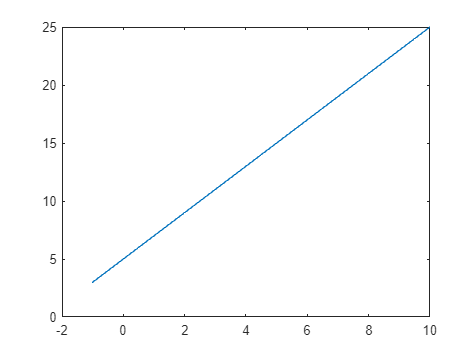

TSN = TSN';

[ndata] = CMO_Interp1PartWT(DS, TS, TSN, 0, -1.5);


figure
plot(TS, DS)

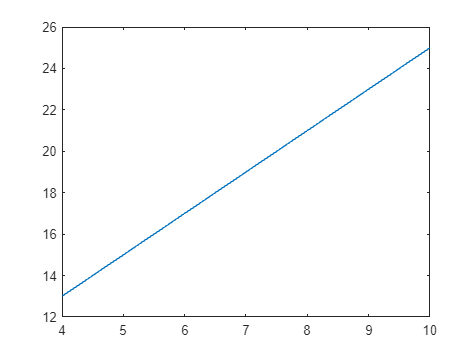

figure
plot(TSN, ndata)

function [hand,q] = CreateHand()
    %hand = SGhuman24DoF;
    hand 
    [q, S] = SGsantelloSynergies;
    hand = SGdefineSynergies(hand,S,1:15);
end

function hand = MoveHand(hand,qdeg)
    q = deg2rad(qdeg);
    hand = SGmoveHand(hand,q)
end

function hand = MoveHandRad(hand,qdeg)
    q = deg2rad(qdeg);
    hand = SGmoveHand(hand,q)
end

function HandPlot(hand, t, Look, Limits)
    figure(t)
    SGplotHand(hand);
    %axis('equal')
    axis on
    grid on 
    view(Look);
    axis(Limits)
end

function HandAnim(hand, Qhand, t, Look, Limits, jointplot, restplot, name)
    %kell 6 frame
    frame = 0;
    [~,Ijm]=max(jointplot);
    [~,Irm]=max(restplot);
    lastsmall=1;
    step = true;
    for i = 1:size(Qhand,2)
        
         hand = MoveHand(hand,Qhand(:,i));
         fig = figure(t);
         SGplotHand(hand);
         axis on
         grid on 
         view(Look);
         axis(Limits);
         drawnow;
         
         
         if ~(i==size(Qhand,2))
             if (jointplot(lastsmall+1)==0) & step
                 lastsmall = lastsmall+1;
             else
                 step = false;
                 if (i == lastsmall) | (i==Ijm)| (i==Irm)| (i==round((Ijm-Irm)/2)+Irm)| (i==round((Irm-lastsmall)/2)+lastsmall)
                       frame = frame+1;
                        print(fig,[name,'_handanim_',num2str(frame)],'-dpng');
            
                 end
             end
         end
         
           
    end
    img(1,:,:,:,:,:) = imread([name,'_handanim_',num2str(1), '.png']);
    for i = 1:frame
        img(i+1,:,:,:,:,:) = imread([name,'_handanim_',num2str(i), '.png']);
        delete( [name,'_handanim_',num2str(i), '.png']);
    end
    img(frame+2,:,:,:,:,:) = img(frame+1,:,:,:,:,:);
    %img = -img+256;
    
    for i = 1:frame+1
        %a1*q1(1-q2)+a2*q2 = a3
        img(i+1,:,:,:,:,:) = img(i,:,:,:,:,:)*0.5 + 0.5*img(i+1,:,:,:,:,:);
    end
    %img(8:14,:,:,:,:,:) = img(1:7,:,:,:,:,:);
    %img = mean(img,1);
    %img = -img+256;
    fig = figure(t+1);
    imagesc(squeeze(img(end,:,:,:,:,:)));
    print(fig,[name,'_handanim_reprent'],'-dpng');
end

function  [dist] = distance(pointA, pointB, metric)
    dist = metric(pointA-pointB);
end